                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2    5.580149e+00    0.000e+00    3.208e+00
    1       4    2.359141e+00    0.000e+00    3.381e+00    3.180e+00
    2       6    3.789739e-01    0.000e+00    1.671e+00    1.628e+00
    3       8    1.703272e-02    0.000e+00    3.525e-01    5.414e-01
    4      10    4.182909e-08    0.000e+00    9.957e-03    9.387e-02
    5      12    5.619956e-07    0.000e+00    2.000e-03    3.563e-04
    6      14    4.074900e-11    0.000e+00    2.010e-05    4.858e-04
    7      16    2.592799e-15    0.000e+00    2.000e-07    4.205e-06


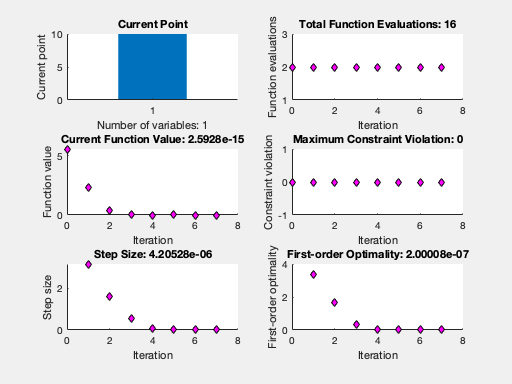


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Pass fixed parameters to objfun
objfun = @(g)misfit(g,thetaexp,t);

% Set nondefault solver options
options = optimoptions("fmincon","Display","iter","PlotFcn",["optimplotx",...
    "optimplotfunccount","optimplotfval","optimplotconstrviolation",...
    "optimplotstepsize","optimplotfirstorderopt"]);

% Solve
[solution,objectiveValue] = fmincon(objfun,g0,[],[],[],[],zeros(size(g0)),[],...
    [],options);


% Clear variables
clearvars objfun options